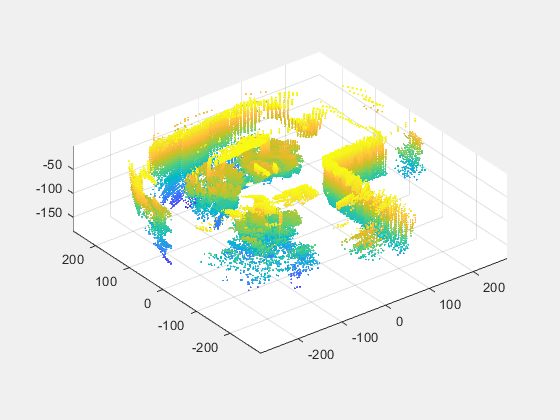

% 本算法采用特征点匹配，ICP，回环检测，运动平均算法
clc;clear;close all;

addpath('./flann/');
addpath('./estimateRigidTransform');
eigDGridStep = 2.0;
% eigLoGridStep=0.03;

readnum=942;           
% scannum=length(dir(datapath))-2;
overlap = 0.35;
icpToler= 3;
ICPthreashold= 100;
maxPairDistance=1.2;
res= 1;
s= 1;
% clouds=readCloudCsv(filepath,filePrefix,readnum,0.6 ,s);
load hannover2zoomed.mat;

generalTime=tic;
N = length(clouds);
MotionGlobal{1}=eye(4);
globalCameraPosition=[0,0,0];
relativeMotion{1}=eye(4);
LoopDectNum=10;%floor(N/4);
cameraPosePair=[];
LoopFlag=0;
ns={};
fixedPointCloudN={};
%% 　主循环
for i=2:15
    Model=clouds{i-1}.Location';
    Data=clouds{i}.Location';
    R0=relativeMotion{i-1}(1:3,1:3);
    t0=relativeMotion{i-1}(1:3,4);
    [MSE(i,1),R,t] = TrICP(Model, Data, R0, t0, ICPthreashold, overlap);
    relativeMotion{i}=Rt2M(R,t);
    if(MSE(i,1)>icpToler )   %单帧配准误差过大,   
          [relativeMotion{i}, MSE(i,1)]=matchFix(clouds{i-1},clouds{i},overlap,eigDGridStep,res);
%           fixedPointCloudN=[fixedPointCloudN ,i];
    end
    MotionGlobal{i}=MotionGlobal{i-1}*relativeMotion{i};
    globalCameraPosition(i,:)=MotionGlobal{i}(1:3,4)';
    
    
end
obtainResult(clouds,MotionGlobal);

    %% 回环检测开始
    LoopPairNum=size(cameraPosePair,1);
    if(size(globalCameraPosition,1)>LoopDectNum)
        [cameraPosePair,LoopFlag]=estimateLoop(globalCameraPosition,cameraPosePair,LoopDectNum,maxPairDistance,LoopFlag);
    end
    %% 回环结束_特征点匹配_匹配对扩展
    if((LoopPairNum==size(cameraPosePair,1) || i==N) && (LoopFlag==1 ))
        routeDisplay(MotionGlobal,'b-*',true);
        accMotion=fastDesEigMatch(clouds,cameraPosePair,overlap,eigDGridStep,res);
        beforeMotion=(2:length(relativeMotion));
        fixMotion=arrayfun(@(x) {relativeMotion{x},x-1,x} , beforeMotion ,'UniformOutput',false ); %补上前面fix结果
        for f=1:length(fixMotion)
            accMotion=[accMotion;fixMotion{f}];
        end
        D=gen_Dij(accMotion,i);
        updatedGlobalMotion=MotionAverage(accMotion,MotionGlobal,D,size(accMotion,1),i);
        for k=1:length(updatedGlobalMotion)
            MotionGlobal{k}=updatedGlobalMotion{k};
        end
        LoopFlag=0;
    end
        
% end
generalTime=toc(generalTime)
routeDisplay(MotionGlobal,'r-o',false);
% MotionGlobal=cellfun(@(b) b(1:3,4) ,(cellfun(@(a) inv(a) ,MotionGlobal ,'UniformOutput',false)),'UniformOutput',false);
% load Hannover_GRpose.mat
% load getmove.mat
% getMove(:,1)=zeros(length(getMove),1);
% routeDisplay(getMove,'r-o',false);
% pose(:,1)=zeros(length(pose),1);
% routeDisplay(pose,'g-s',false);

obtainResult(clouds,MotionGlobal);


